# Read Data, Manipulate, and Combine

## Read Admissions Data

T = readtable('ADMISSIONS.csv');
head(T)

ans = 8×19 table
    ROW_ID    SUBJECT_ID     HADM_ID           ADMITTIME              DISCHTIME         DEATHTIME    ADMISSION_TYPE         ADMISSION_LOCATION               DISCHARGE_LOCATION           INSURANCE       LANGUAGE           RELIGION           MARITAL_STATUS            ETHNICITY                 EDREGTIME              EDOUTTIME                                  DIAGNOSIS                              HOSPITAL_EXPIRE_FLAG    HAS_CHARTEVENTS_DATA
    ______    __________    __________    ___________________    ___________________    _________    _______

% save ADMISSION.mat % save data for faster access in future

If the data has been read and saved as a .mat file, load the data.

% load ADMISSION.mat

Sort by subject ID and admission time.

T = sortrows(T,{'SUBJECT_ID', 'ADMITTIME'},{'ascend', 'ascend'});
head(T)

ans = 8×19 table
    ROW_ID    SUBJECT_ID     HADM_ID           ADMITTIME              DISCHTIME              DEATHTIME         ADMISSION_TYPE         ADMISSION_LOCATION               DISCHARGE_LOCATION           INSURANCE       LANGUAGE           RELIGION           MARITAL_STATUS            ETHNICITY                 EDREGTIME              EDOUTTIME                        DIAGNOSIS                   HOSPITAL_EXPIRE_FLAG    HAS_CHARTEVENTS_DATA
    ______    __________    __________    ___________________    ___________________    ___________________    ________

Next, find readmissions that are not electives and plot unintended readmissions.

T.ADMISSION_TYPE = categorical(T.ADMISSION_TYPE);
idx = ismember(T.ADMISSION_TYPE, {'NEWBORN', 'ELECTIVE'});
T(idx, :) = [];
[B, BG] = groupcounts(T.SUBJECT_ID); % Find how many visits per subject
idx = ismember(T.SUBJECT_ID, BG(B>1)); % which rows have subjects with multiple visits (>1)
T(~idx, :) = []; % keep only repeat visitors
head(T)

ans = 8×19 table
    ROW_ID    SUBJECT_ID     HADM_ID           ADMITTIME              DISCHTIME              DEATHTIME         ADMISSION_TYPE         ADMISSION_LOCATION               DISCHARGE_LOCATION          INSURANCE       LANGUAGE         RELIGION         MARITAL_STATUS    ETHNICITY         EDREGTIME              EDOUTTIME                                   DIAGNOSIS                              HOSPITAL_EXPIRE_FLAG    HAS_CHARTEVENTS_DATA
    ______    __________    __________    ___________________    ___________________    ___________________    _______

T.NEXTADMITTIME = T.ADMITTIME;
T.NEXTADMITTIME(1:end-1) = T.ADMITTIME(2:end);
T.NEXTADMISSION_TYPE = T.ADMISSION_TYPE;
T.NEXTADMISSION_TYPE(1:end-1) = T.ADMISSION_TYPE(2:end);
T.TIMELAPSE = T.NEXTADMITTIME - T.ADMITTIME;
[uniqueS, is] = unique(T.SUBJECT_ID, 'last');
T(is, :) = [];
head(T)

ans = 8×22 table
    ROW_ID    SUBJECT_ID     HADM_ID           ADMITTIME              DISCHTIME         DEATHTIME    ADMISSION_TYPE         ADMISSION_LOCATION               DISCHARGE_LOCATION          INSURANCE       LANGUAGE           RELIGION           MARITAL_STATUS            ETHNICITY                  EDREGTIME              EDOUTTIME                                   DIAGNOSIS                              HOSPITAL_EXPIRE_FLAG    HAS_CHARTEVENTS_DATA       NEXTADMITTIME       NEXTADMISSION_TYPE     TIMELAPSE 
    ______    __________    __________    _____

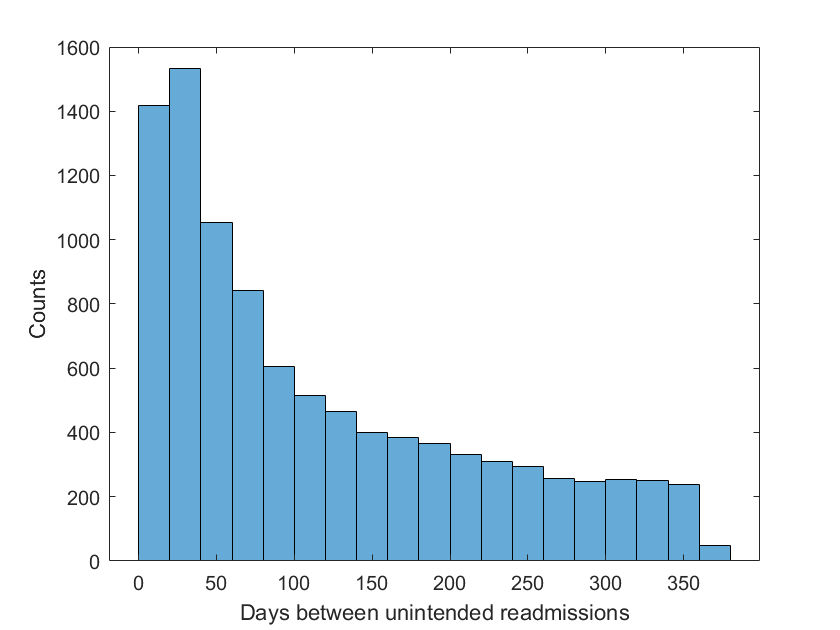

histogram(day(T.TIMELAPSE))
xlabel('Days between unintended readmissions')
ylabel('Counts')

## Read Notes Data 

Read the notes entered by doctors and nurses corresponding to the hospital admissions.

opts = detectImportOptions("NOTEEVENTS.csv"); % helpful for reading large excel files
Notes = readtable("NOTEEVENTS.csv", opts);
% save Notes.mat
% load Notes.mat % Load the notes if the data has been saved before
head(Notes)

ans = 8×11 table
    ROW_ID    SUBJECT_ID     HADM_ID      CHARTDATE     CHARTTIME     STORETIME           CATEGORY           DESCRIPTION       CGID        ISERROR                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           

Keep notes for repeat visitors, and join admissions data with notes using hospital admission IDs. Live Task for joining tables can be an easy way to visualize and control joining of tables. 

idx = ismember(Notes.SUBJECT_ID, T.SUBJECT_ID); % repeat visitors in Notes
Notes(~idx, :) = [];
joinedData = innerjoin(T,Notes,'Keys',{'HADM_ID'});
Data = joinedData(:, {'SUBJECT_ID_T', 'HADM_ID', 'ADMITTIME', 'DISCHTIME', 'DEATHTIME', 'ADMISSION_TYPE','HOSPITAL_EXPIRE_FLAG', 'CATEGORY', 'DESCRIPTION', 'TEXT', 'NEXTADMITTIME', 'NEXTADMISSION_TYPE', 'TIMELAPSE'}); % only keep relevant information
Data = sortrows(Data, {'SUBJECT_ID_T', 'ADMITTIME'}, {'ascend', 'ascend'});
head(Data)

ans = 8×13 table
    SUBJECT_ID_T     HADM_ID           ADMITTIME              DISCHTIME         DEATHTIME    ADMISSION_TYPE    HOSPITAL_EXPIRE_FLAG          CATEGORY           DESCRIPTION                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   

Plot the categories of notes to decide which ones to keep for further analysis.

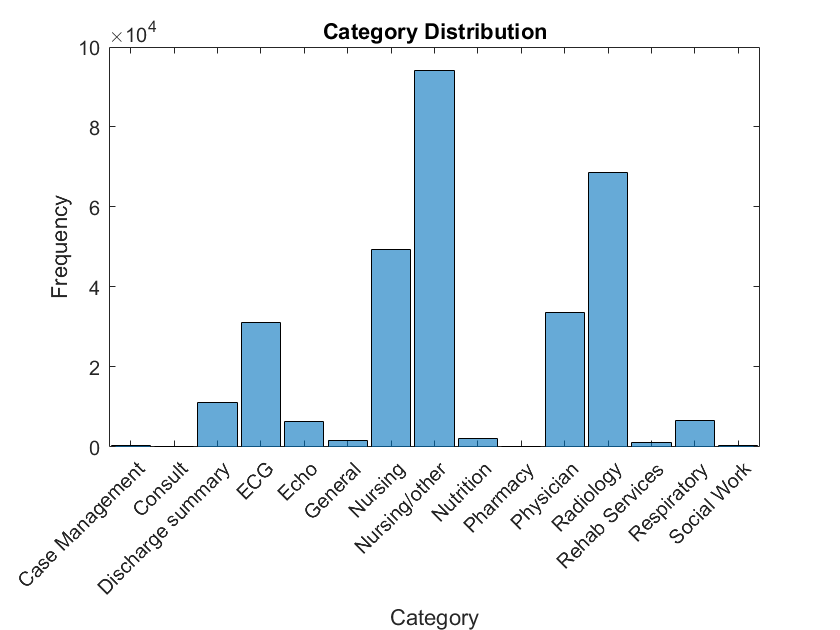

Data.CATEGORY = categorical(Data.CATEGORY);
histogram(Data.CATEGORY)
xlabel("Category")
ylabel("Frequency")
title("Category Distribution")

Assuming that discharge summary is the most indicative of whether there will be readmission or not, we are going to use discharge summary only. Alternatively, we could combine all notes and use those as predictors.

Data.Notes = strings(size(Data, 1), 1);
[uniqueHad1, ihad1] = unique(Data.HADM_ID, 'first'); %1st appearance
[uniqueHad2, ihad2] = unique(Data.HADM_ID, 'last'); %last appearance
for i = 1:length(uniqueHad1)
    checklen = numel(Data.TEXT(Data.CATEGORY(ihad1(i):ihad2(i))=="Discharge summary"));
    
    if checklen ~= 0
        txt = Data.TEXT(ihad1(i):ihad2(i));
        Data.Notes(ihad2(i)) = join(txt(Data.CATEGORY(ihad1(i):ihad2(i))=="Discharge summary")); % joining to avoid multiple discharge summaries
    end
end
idx = strlength(Data.Notes)>0; % keep the ones that has some notes
Data1 = Data(idx, :); 
head(Data1)

ans = 8×14 table
    SUBJECT_ID_T     HADM_ID           ADMITTIME              DISCHTIME         DEATHTIME    ADMISSION_TYPE    HOSPITAL_EXPIRE_FLAG      CATEGORY             DESCRIPTION                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

Now, let's create a variable to indicate if someone was admitted to hospital within 30 days.

idx = days(Data1.TIMELAPSE)<=30;
Data1.LAPSE_FLAG = zeros(size(Data1, 1), 1);
Data1.LAPSE_FLAG(idx) = 1;
% save Data1.mat

Next, we will evaluate different machine learning models using classification learner app.

edit Preprocess_MIMIC_Demo_02.mlx